# Gabriel Colangelo HW4

clear
close all
clc

## Problem 1a)


$$\underline{Find}: p,h, period, r_p, r_a, \epsilon, r_0, v_0, \dot{r}_0, \dot{\theta}_0, \gamma_0, E_0$$


% Given: 1/1/1996
a       = 1.43018128;               % Semi major axis [AU]
e       = 0.2576460;                % Eccentricity
ta0     = 118.65;                   % True anomaly [deg]
mu_sun  = 132712440017.99;          % Sun gravitional parameter [km^3/s^2] 
mu_sun  = mu_sun*(1/149597898)^3;   % Sun gravitional parameter [AU^3/s^2]

% Semi latus rectum [AU]
p       = a*(1 - e^2); 
fprintf('p = %.5f [AU] \n', p);

p = 1.33524 [AU] 



$$p = a(1 - e^2) = 1.33524 \ [AU]$$


% Specific angular momentum [AU^2/s]
h       = sqrt(p*mu_sun);
fprintf('h = %.5E [km^2/s] \n',h*149597898^2)

h = 5.14871E+09 [km^2/s] 



$$h = \sqrt{\mu p} = 5.15\times10^{9} \ [km^2/s]$$


% Period [s]
tau     = 2*pi*sqrt(a^3/mu_sun);
fprintf('Period = %.1f days \n', tau/(24*3600));

Period = 624.7 days 



$$Period = 2\pi \sqrt{a^3/\mu} = 624.7 \ days$$


% Distance to periapsis [AU]
rp      = a*(1 - e);
fprintf('rp = %.5f [AU] \n', rp);

rp = 1.06170 [AU] 



$$r_P = a(1-e) = 1.0617 \ [AU]$$


% Distance to apoapsis [AU]
ra      = a*(1 + e);
fprintf('ra = %.5f [AU] \n', ra);

ra = 1.79866 [AU] 



$$r_a = a(1+e) = 1.79866 \ [AU]$$


% Specific Energy [AU^2/s^2]
energy  = -mu_sun/(2*a);
fprintf('Energy = %.3f [km^2/s^2] \n', energy*149597898^2)

Energy = -310.145 [km^2/s^2] 



$$\epsilon =  -\frac{\mu}{2a} = -310.145 \ [km^2/s^2]$$


% Initial radial distance [AU]
r0      = p/(1 + e*cosd(ta0));
fprintf('r0 = %.5f [AU] \n', r0)

r0 = 1.52343 [AU] 



$$r_0 = \frac{p}{(1 + e\cos{\theta_0^*})} = 1.523 \ [AU]$$


% Initial velocity magnitude [AU/s]
v0      = sqrt(2*(energy + mu_sun/r0));
fprintf('v0 = %.2f [km/s] \n', v0*149597898)

v0 = 23.33 [km/s] 



$$\epsilon = \frac{v_0^2}{2} - \frac{\mu}{r_0} \\v_0 = \sqrt{2(\epsilon + \frac{\mu}{r_0})}  = 23.33 \ [km/s]$$
 

% Initial true anomaly angular rate [rad/s]
ta0_dot  = (h/r0^2);
fprintf('Initial true anomaly angular rate = %.5E [deg/s] \n', ta0_dot*180/pi);

Initial true anomaly angular rate = 5.67967E-06 [deg/s] 



$$h  = r_0^2 \dot{\theta}_0 \\
\dot{\theta}_0 = \frac{h}{r_0^2} = 5.679\times10^{-6} \ [deg/s]$$


% Initial radial velocity magnitude [AU/s]
r0_dot  = sqrt(v0^2 - r0^2*ta0_dot^2);
fprintf('Initial radial velocity magnitude = %.2f [km/s] \n', r0_dot*149597898);

Initial radial velocity magnitude = 5.83 [km/s] 



$$v_0^2 = \dot{r_0}^2 + r_0^2 \dot{\theta}_0^2\\
\dot{r}_0 = \sqrt{v_0^2 - r_0^2 \dot{\theta}_0^2} = 5.83 \ [km/s]$$


% Initial flight path angle
gamma0  = atan2d(r0_dot,(r0*ta0_dot));
fprintf('Initial flight path angle = %.5f [deg] \n',gamma0);

Initial flight path angle = 14.46511 [deg] 



$$\gamma = \tan^{-1}({\frac{\dot{r}_0}{r_0 \dot{\theta}_0}) = \tan^{-1}({\frac{v_r}{v_{\theta}}) = 14.46 \ [deg]$$


% Initial eccentric anomaly
E0      = 2*atan2d(tand(ta0/2),sqrt((1+e)/(1-e)));
fprintf('E0 = %.5f [deg] \n', E0)

E0 = 104.65950 [deg] 



$$\tan({\frac{\theta^*_0}{2}) = \sqrt{\frac{1+e}{1-e}} \tan({\frac{E_0}{2}) \\

E_0 = 2\tan^{-1}{[\tan({\frac{\theta^*_0}{2}) /\sqrt{\frac{1+e}{1-e}} ]} = 104.66 \ [deg]$$


% Time from last perihelion [s]
delta_t = ((E0*pi/180) - e*sind(E0))/(sqrt(mu_sun/a^3));

% Time to next perihelion [s]
tnp     = tau - delta_t;
fprintf('Time to next perihelion is %.1f days', tnp/(24*3600));

Time to next perihelion is 467.9 days


$$\sqrt{\frac{\mu}{a^3}} (t - t_p) = E - e\sin{E} \\
\Delta t = \frac{E_0 - e\sin{E_0}}{\sqrt{\frac{\mu}{a^3}}} \\
period - \Delta t = 467.9 \ days \ to \ next \ perihelion$$


**The asteroid is currently ascending, this is known because both the true anomaly and flight path angle are positive.**

% Write initial position and velocity vectors in rotating orbit frame (r,theta)
r0_O    = [r0;0;0];
v0_O    = [r0_dot;r0*ta0_dot;0];


$$\bar{r}_0 = r_0 \hat{r}  = 1.5234 \ \hat{r}  \ [AU] \\
\bar{v}_0 = \dot{r}_0 \hat{r} + r_0 \dot{\theta}_0 \ \hat{\theta} = 5.83 \ \hat{r} +  22.59\ \hat{\theta} \ [km/s]$$


% DCM matrix from rotating orbit frame to perifocal frame
P_DCM_O = [cosd(ta0), -sind(ta0), 0;...
           sind(ta0), cosd(ta0), 0;...
           0, 0, 1];

% Rotate position and velocity vectors from rotating orbit frame to
% perifocal inertial frame
r0_P     = P_DCM_O*r0_O;
v0_P     = P_DCM_O*v0_O;


$$[r_0]^P = [PO] [r_0]^O \\
[v_0]^P = [PO] [v_0]^O \\
\bar{r}_0 =-0.7304 \ \hat{e} +  1.3369 \ \hat{p}\ [AU] \\
\bar{v}_0 =  -22.62 \ \hat{e} + -5.72 \ \hat{p} \ [km/s]$$


## Problem 1b) Plot Orbit

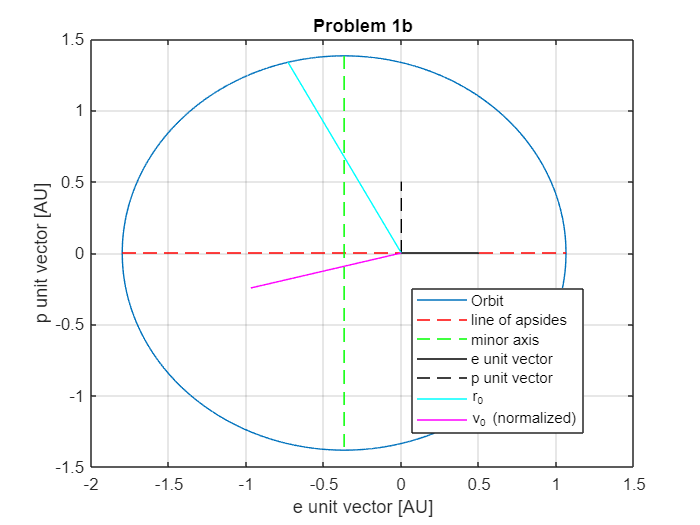

% Initial Mean anomaly
M0      = (E0*pi/180) - e*sind(E0);

% Semi-minor axis
b       = a*sqrt(1-e^2);

% Mean angular motion
n       = sqrt(mu_sun/a^3); 

% Define time - increment by 30 minutes
time    = 0:1800:tau;

% Initialize Perifocal position and velocity vector
r_P     = zeros(2,length(time)); 
v_P     = zeros(2,length(time));

% Calculate vectors in perifocal coordinates for each time step using
% Keplers Equation
for i = 1:length(time)
    
    % Calculate Mean Anonamly 
    M           = M0 + (n*(time(i)- time(1))); 

    % Calculate Eccentric anomaly [rad]
    E           = CalcEccentricAnomaly(e, M);
    
    % Position Vector in Perifocal Frame 
    r_P(:,i)    = [a*(cos(E) - e);b*sin(E)]; 

    % Velocity Vector in Perifocal Frame
    v_P(:,i)    = [-a^2*n*sin(E)/norm(r_P(:,i)); a*b*n*cos(E)/norm(r_P(:,i))];
end

figure
plot(r_P(1,:),r_P(2,:))
title('Problem 1b')
hold on
xlabel('e unit vector [AU]')
ylabel('p unit vector [AU]')
line([-ra rp],[0 0],'Color','red','LineStyle','--')
line([-a*e -a*e],[b,-b],'Color','green','LineStyle','--')
line([0 .5],[0 0],'Color','black','LineStyle','-')
line([0 0],[0 .5],'Color','black','LineStyle','--')
line([0 r0_P(1)],[0 r0_P(2)],'Color','cyan','LineStyle','-')
line([0 v0_P(1)/norm(v0_P)],[0 v0_P(2)/norm(v0_P)],'Color','magenta','LineStyle','-')
legend('Orbit','line of apsides','minor axis',...
       'e unit vector', 'p unit vector', 'r_0',...
       'v_0 (normalized)','Location','best')
grid on 
hold off

## Problem 1c)


$$\underline{Find}: \bar{r}_1, \bar{v}_1, \dot{r}_1, \dot{\theta}_1, \gamma_1, E_1, \theta_1^*$$


% Convert change in time to seconds
dt         = seconds(datetime(1996,7,11,0,0,0,0) - datetime(1996,1,1,0,0,0,0));%

% Calculate Mean anomaly at t1
M1          = M0 + n*dt; 

% Calculate Eccentric anomaly at t1 [rad]
E1         = CalcEccentricAnomaly(e, M1);
fprintf('Eccentric anomaly at t1 = %.3f [deg] \n', E1*180/pi)

Eccentric anomaly at t1 = 196.762 [deg] 



$$M_1 = M_0 + n(t_1 - t_0) = E_1 - e\sin{E_1} \\
E_1 = 196.76 \ [deg]$$


% Position Vector in Perifocal Frame at t1
r1_P       = [a*(cos(E1) - e);b*sin(E1)];


$$\bar{r}_1 = a(\cos{E_1} - e)\hat{e} + b\sin{E_1}\hat{p} = -1.738\ \hat{e} -0.398\ \hat{p}\ [AU]$$


% Velocity Vector in Perifocal Frame at t1
v1_P       = [-a^2*n*sin(E1)/norm(r1_P); a*b*n*cos(E1)/norm(r1_P)];


$$\bar{v}_1 = \frac{-a^2n\sin{E_1}}{r_1} \hat{e} + \frac{abn\cos{E_1}}{r_1}\hat{p} = 5.76 \ \hat{e} -18.48\ \hat{p} \ [km/s]$$


% Calculate true anomaly at t1
ta1        = 2*atan2d(tan(E1/2)*sqrt(1+e),sqrt(1-e));
fprintf('True anomaly at t1 = %.5f [deg] \n', ta1)

True anomaly at t1 = -167.08401 [deg] 



$$\tan({\frac{\theta^*_1}{2}) = \sqrt{\frac{1+e}{1-e}} \tan({\frac{E_1}{2}) \\

\theta^*_1 = 2\tan^{-1}{[\tan({\frac{E_1}{2}) \sqrt{\frac{1+e}{1-e}} ]} = -167.1 \ [deg]$$


% True anomaly angular rate at t1 [rad/s]
ta1_dot  = (h/norm(r1_P)^2);
fprintf('True anomaly angular rate at t1 = %.5E [deg/s] \n', ta1_dot*180/pi);

True anomaly angular rate at t1 = 4.14634E-06 [deg/s] 



$$h  = r_1^2 \dot{\theta}_1 \\
\dot{\theta}_1 = \frac{h}{r_1^2} = 4.146\times10^{-6} \ [deg/s]$$


% Rotate  velocity vector from Perifocal frame to Orbit frame
O_DCM_P = [cosd(ta1), sind(ta1), 0;...
           -sind(ta1), cosd(ta1), 0;...
           0, 0, 1];
v1_O    = O_DCM_P*[v1_P;0];

% Extract radial component of velocity
fprintf('Radial velocity at t1 = %.2f [km/s] \n', v1_O(1)*149597898);

Radial velocity at t1 = -1.48 [km/s] 



$$[v_1]^O = [OP] [v_1]^P  = \dot{r}_1\hat{r}  + r_1 \dot{\theta}_1 \hat{\theta}\\
\dot{r}_1 = -1.48\ [km/s]$$


% Flight path angle at t1
gamma1  = atan2d(v1_O(1),v1_O(2));
fprintf('Flight path angle at t1 = %.5f [deg] \n',gamma1);

Flight path angle at t1 = -4.39749 [deg] 



$$\gamma = \tan^{-1}({\frac{\dot{r}_1}{r_1 \dot{\theta}_1}) = \tan^{-1}({\frac{v_r}{v_{\theta}}) = -4.39 \ [deg]$$


## Problem 1d)

The new state is in the **third quadrant**. This is known because the position vector has negative $\hat{e}$ and negative $\hat{p}$ components, which correspond to a true anomaly of -166 degrees (or 194 degrees), which is in the third quadrant. The flight path angle is also negative. 

The new state is 192 days past the original state which was 467.9 days from perihelion. Therefore, the new state **275.9 days away from perihelion**.

## Problem 1e)

The** asteroid will never cross Earth's orbit**, because the value of it's periapsis is 1.06 [AU]. 1 AU is defined as the average Earth-Sun distance. Because the closest the asteroid ever is to the sun is greater than 1 AU, the asteroid will always be outside of the Earth's orbit about the sun.

## Problem 2a)

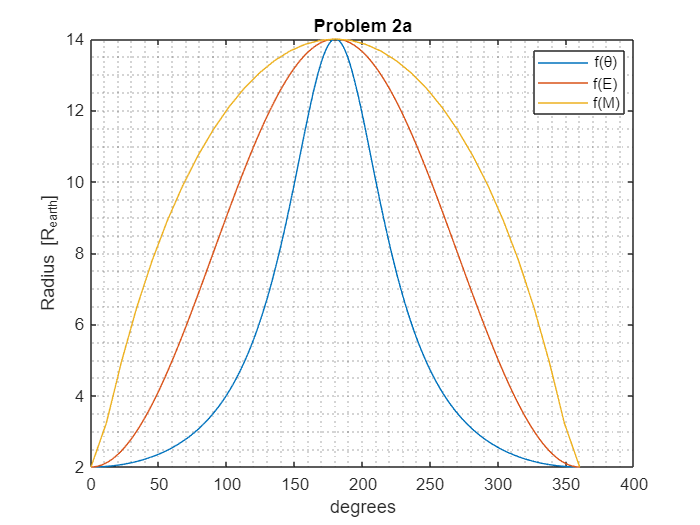

% Satellite orbit parameters about Earth
e       = 0.75;
a       = 8;    % Earth Radii

% Choose range of true anomaly values [deg]
ta_vec  = 0:.001:360;

% Calculate Eccentric anomaly based of true anomaly [deg]
E_ta    = 2*atan2d(tand(ta_vec/2),sqrt((1+e)/(1-e)));

% Radius as function of true anomaly
r_ta    = a*(1 - e*cosd(E_ta));

% Choose range of Eccentric anomaly values
E_vec   = 0:.001:360;

% Radius as function of Eccentric anomaly
r_E     = a*(1 - e*cosd(E_vec));

% Choose range of Mean anomaly values
M_vec   =  0:pi/16:2*pi;

% Initialize Eccentric anomaly vector
E_M     = zeros(size(M_vec));

% Solver Keplers Equation for each mean anomaly [rad]
for i = 1:length(M_vec)
    E_M(i)  = CalcEccentricAnomaly(e,M_vec(i));
end

% Radius as function of Mean anomaly
r_M     = a*(1 - e*cos(E_M));

figure
plot(ta_vec, r_ta, E_vec, r_E, M_vec*180/pi,r_M)
grid minor
legend('f(\theta)','f(E)','f(M)','Location','best')
xlabel('degrees')
ylabel('Radius [R_{earth}]')
title('Problem 2a')

The** fastest angular rate is associated with true anomaly**, while the **slowest is associated with the mean anomaly**. The **steepest slope is the true anomaly**, while the **shallowest slope is the mean anomaly**. Kepler's equation is** difficult to solve at the apse points because of how the slope approches zero at the apse**. Kepler's equation is solved using the Newton-Raphson method, in which the slope/derivative plays a major part in the algorithm. If the derivative goes to zero, the solver convergence is not guranteed, and if it does converge, may be slow.

## Problem 2b)


$$\underline{Find}: E, \theta^*, p,h,r_p,r_a,period, \epsilon, r, v, \gamma, (t - t_p)$$


% Get radius of orbit when mean anomaly is 90 degrees
r_M90      = r_M(find(M_vec >= pi/2,1));
fprintf('When the mean anomaly is at 90 degrees, the vehicle is at a radius of %.2f Earth Radii',r_M90);

When the mean anomaly is at 90 degrees, the vehicle is at a radius of 11.45 Earth Radii

% Find Eccentric anomaly for M = 90 degrees
E_M90      = E_vec(find(r_E >= r_M90,1));
fprintf('The eccentric anomaly for a mean anomaly of 90 degrees is %.2f [deg]',E_M90);

The eccentric anomaly for a mean anomaly of 90 degrees is 125.14 [deg]

% Calculate true anomaly based of eccentric anomaly for M = 90 deg
ta_M90      = E_vec(find(r_ta >= r_M90,1));
fprintf('The true anomaly for a mean anomaly of 90 degrees is %.2f [deg]',ta_M90);

The true anomaly for a mean anomaly of 90 degrees is 157.80 [deg]

**When the mean anomaly is 90 degrees, the satellite is at 11.45 Earth Radii with an eccentric anomaly  of **$E$** = 125.14 degrees, and a true anomaly of **$\theta^* = 157.80$ **degrees.**

% Calculate semi-latus rectum
p_M90       = a*(1 - e^2);
fprintf('The semi-latus rectum is %.2f Earth Radii \n',p_M90)

The semi-latus rectum is 3.50 Earth Radii 



$$p = a(1 - e^2) = 3.5 \ [R_{earth}]$$


% Convert Gravitational parameter to R_earth^3/s^2
mu_earth    = 398600.4415*(1/6378.1363)^3;
% Calculate specific angular momentum
h_M90       = sqrt(p_M90*mu_earth);
fprintf('The satellite specific angular momentum is %.3E [km^2/s]',h_M90*6378.1363^2);

The satellite specific angular momentum is 9.433E+04 [km^2/s]


$$h = \sqrt{\mu p} = 9.433 \times 10^{4} \ [km^2/s]$$


% Calculate periapsis
rp_M90      = a*(1 - e);
fprintf('Satellite orbital rp = %.2f Earth Radii \n', rp_M90);

Satellite orbital rp = 2.00 Earth Radii 



$$r_P = a(1-e) = 2 \ [R_{earth}]$$


% Calculate apoapsis 
ra_M90      = a*(1 + e);
fprintf('Satellite orbtial ra = %.2f Earth Radii \n', ra_M90);

Satellite orbtial ra = 14.00 Earth Radii 



$$r_a = a(1+e) = 14 \ [R_{earth}]$$


% Calulcate Period [s]
tau_M90     = 2*pi*sqrt(a^3/mu_earth);
fprintf('Satellite orbital period = %.2f days \n', tau_M90/(24*3600));

Satellite orbital period = 1.33 days 



$$Period = 2\pi \sqrt{a^3/\mu} = 1.33 \ days$$


% Specific Energy
energy_M90  = -mu_earth/(2*a);
fprintf('Satellite orbital specific energy is = %.2f [km^2/s^2]\n', energy_M90*6378.1363^2)

Satellite orbital specific energy is = -3.91 [km^2/s^2]



$$\epsilon =  -\frac{\mu}{2a} = -3.91\ [km^2/s^2]$$


% Velocity magnitude [AU/s]
v_M90       = sqrt(2*(energy_M90 + mu_earth/r_M90));
fprintf('Velocity magnitude at this location = %.2f [km/s]  \n', v_M90*6378.1363)

Velocity magnitude at this location = 1.76 [km/s]  



$$\epsilon = \frac{v^2}{2} - \frac{\mu}{r} \\v = \sqrt{2(\epsilon + \frac{\mu}{r})}  =1.76 \ [km/s]$$
 

% Flight path angle
gamma_M90  = acosd(h_M90/(r_M90*v_M90));
fprintf('Flight path angle at this location = %.5f [deg] \n',gamma_M90);

Flight path angle at this location = 42.83785 [deg] 



$$\gamma = \cos^{-1}({\frac{h}{r v}) = 42.84 \ [deg]$$


% Time from last perihelion [s]
dtp_M90    = ((E_M90*pi/180) - e*sind(E_M90))/(sqrt(mu_earth/a^3));
fprintf('Time from last perihelion is %.1f hours', dtp_M90/(3600));

Time from last perihelion is 8.0 hours


$$\sqrt{\frac{\mu}{a^3}} (t - t_p) = E - e\sin{E} \\
(t - t_p)= \frac{E - e\sin{E}}{\sqrt{\frac{\mu}{a^3}}} = 8 \ [hrs]$$


## Problem 2c)


$$\underline{Find}: \bar{r}_0, \bar{v}_0 \ in \ \hat{e}, \hat{p}, \hat{r}, \hat{\theta}$$


% Mean motion
n          = sqrt(mu_earth/a^3);

% Semi-minor axis
b          = a*sqrt(1-e^2);

% Initial position in perifocal coordinates
r0_P_fg    = [a*(cosd(E_M90) - e);b*sind(E_M90)]; 


$$\bar{r}_0 = a(\cos{E} - e)\hat{e} + b\sin{E}\hat{p} = -10.60\ \hat{e} + 4.33\ \hat{p}\ [R_{earth}]$$


% Velocity Vector in Perifocal Frame
v0_P_fg    = [-a^2*n*sind(E_M90)/norm(r0_P_fg); a*b*n*cosd(E_M90)/norm(r0_P_fg)];


$$\bar{v}_0 = \frac{-a^2n\sin{E}}{r_0} \hat{e} + \frac{abn\cos{E}}{r_0}\hat{p} = -1.596 \ \hat{e} -0.743\ \hat{p} \ [km/s]$$


% Rotate  velocity vector from Perifocal frame to Orbit frame
O_DCM_P    = [cosd(ta_M90), sind(ta_M90), 0;...
              -sind(ta_M90), cosd(ta_M90), 0;...
               0, 0, 1];
v0_O_fg    = O_DCM_P*[v0_P_fg;0];
r0_O_fg    = O_DCM_P*[r0_P_fg;0];


$$[v_0]^O = [OP] [v_0]^P = 1.197\ \hat{r} + 1.291\ \hat{\theta}  \ [km/s]\\
[r_0]^O = [OP] [r_0]^P = 11.45 \ \hat{r} \ [R_{earth}]$$


## Problem 2d)


$$\underline{Find}: \theta^*, f,g,\dot{f},\dot{g} $$


% Solve for mean anomaly in 2 hours from prior time when M0 = 90 [rad]
dt          = 2*3600; % 2 hours in seconds
M1_fg       = 90*pi/180 + n*dt;

% Solve for eccentric anomaly at this new time
E1_fg       = CalcEccentricAnomaly(e, M1_fg);

% Calculate true anomaly from eccentric anomaly at new time
ta1_fg      = 2*atan2d(tan(E1_fg/2)*sqrt(1+e),sqrt(1-e));
fprintf('True anomaly at new time = %.5f [deg] \n', ta1_fg)

True anomaly at new time = 164.39251 [deg] 



$$M_1 = M_0 + n(t_1 - t_0) = E_1 - e\sin{E_1} $$



$$\tan({\frac{\theta^*_1}{2}) = \sqrt{\frac{1+e}{1-e}} \tan({\frac{E_1}{2}) \\

\theta^*_1 = 2\tan^{-1}{[\tan({\frac{E_1}{2}) \sqrt{\frac{1+e}{1-e}} ]} = 164.39 \ [deg]$$


% Calculate r at current time
r_fg        = a*(1 - e*cos(E1_fg));

% Calculate f, g, fdot, and gdot using true anomaly
f_ta        = (1 - (r_fg/p_M90)*(1 - cosd(ta1_fg - ta_M90)));
g_ta        = r_fg*norm(r0_P_fg)*sind(ta1_fg - ta_M90)/sqrt(mu_earth*p_M90);
fdot_ta     = (r0_P_fg'*v0_P_fg)*(1 - cosd(ta1_fg - ta_M90))/(p_M90*norm(r0_P_fg)) -...
              (1/norm(r0_P_fg))*sqrt(mu_earth/p_M90)*sind(ta1_fg - ta_M90);
gdot_ta     = (1 - (norm(r0_P_fg)/p_M90)*(1 - cosd(ta1_fg - ta_M90)));
fprintf('Using true anomaly, f is %.3f, g is %.3E, fdot is %.3E, and gdot is %.3f',...
            f_ta,g_ta,fdot_ta,gdot_ta);

Using true anomaly, f is 0.976, g is 7.145E+03, fdot is -6.284E-06, and gdot is 0.978

Note: f and $\dot{g}$ are unitless, while g has units of [sec] and $\dot{f}$ has units of $[sec]^{-1}$


$$f(\theta^*)        = 1 - \frac{r}{p}[1 - \cos{(\theta^* - \theta_0^*)}] \\

g(\theta^*)           = \frac{r r_0}{\sqrt{\mu p}} \sin{(\theta^* - \theta_0^*)} \\

\dot{f}(\theta^*) = \frac{\bar{r}_0 \cdot \bar{v}_0}{p r_0} [1  - \cos{(\theta^* - \theta_0^*)}] - \frac{1}{r_0} \sqrt{\frac{\mu}{p} }\sin{(\theta^* - \theta_0^*)}  \\

\dot{g}(\theta^*)  =  1 - \frac{r_0}{p}[1 - \cos{(\theta^* - \theta_0^*)}]  \\

\bar{r} = f \ \bar{r}_0 + g \ \bar{v}_0 =  0.976 \ \bar{r}_0 + 7.145 \times 10^3 \ \bar{v}_0\\
\bar{v} = \dot{f} \ \bar{r}_0 + \dot{g} \ \bar{v}_0 = -6.284 \times 10^{-6} \ \bar{r}_0  +  0.978\  \bar{v}_0 \\$$


% Calculate f, g, fdot, and gdot using eccentric anomaly
f_E         = (1 - (a/norm(r0_P_fg))*(1 - cos(E1_fg - E_M90*(pi/180))));
g_E         = dt - sqrt(a^3/mu_earth)*(E1_fg - E_M90*(pi/180) - sin(E1_fg - E_M90*(pi/180)));
fdot_E      = -sqrt(mu_earth*a)*sin(E1_fg - E_M90*(pi/180))/(r_fg*norm(r0_P_fg));
gdot_E      = (1 - (a/r_fg)*(1 - cos(E1_fg - E_M90*(pi/180))));
fprintf('Using eccentric anomaly, f is %.3f, g is %.3E, fdot is %.3E, and gdot is %.3f',...
            f_E,g_E,fdot_E,gdot_E);

Using eccentric anomaly, f is 0.976, g is 7.146E+03, fdot is -6.284E-06, and gdot is 0.978

Note: f and $\dot{g}$ are unitless, while g has units of [sec] and $\dot{f}$ has units of $[sec]^{-1}$


$$f(E)        = 1 - \frac{a}{r_0}[1 - \cos{(E- E_0)}] \\

g(E)           = (t - t_0) - \sqrt{\frac{a^3}{\mu}}[E - E_0 - \sin{(E - E_0})] \\

\dot{f}(E) = -\frac{\sqrt{\mu a}}{r r_0} \sin{(E - E_0)} \\

\dot{g}(E)  =  1 - \frac{a}{r}[1 - \cos{(E- E_0)}] \\

\bar{r} = f \ \bar{r}_0 + g \ \bar{v}_0 =  0.976 \ \bar{r}_0 + 7.146 \times 10^3 \ \bar{v}_0\\
\bar{v} = \dot{f} \ \bar{r}_0 + \dot{g} \ \bar{v}_0 = -6.284 \times 10^{-6} \ \bar{r}_0  +  0.978\  \bar{v}_0 \\$$


**Using true anomlay and eccentric anomaly yields the same results, as shown above.  When writing **$\bar{r}$** and **$\bar{v}$**, the vector basis used should be the vector basis associated with the perifocal coordinate system, (i.e **$\hat{e}$** & **$\hat{p}$**).**

## Problem 2e) Plot Orbit

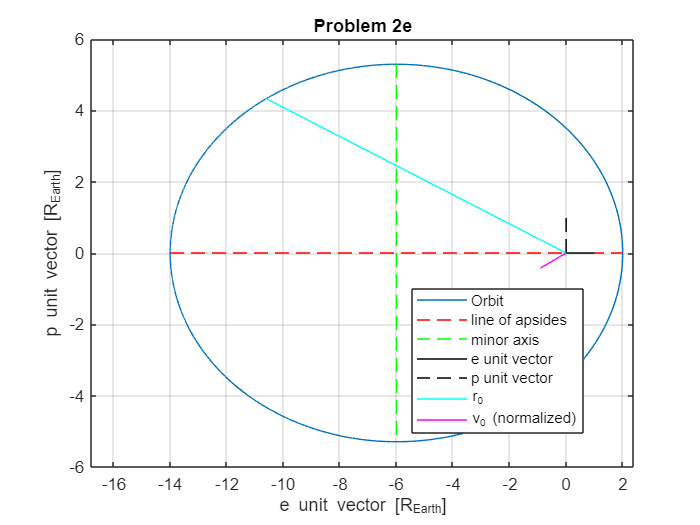

% Define time - increment by 10 second
time    = 0:10:tau_M90;

% Initialize Perifocal position and velocity vector
r_P_fg  = zeros(2,length(time)); 
v_P_fg  = zeros(2,length(time));

% Calculate vectors in perifocal coordinates for each time step using
% Keplers Equation
for i = 1:length(time)

    % Change in time
    dt          = (time(i)- time(1));
    
    % Calculate Mean Anonamly (M0 = 90 degrees)
    M           = pi/2 + n*dt; 

    % Calculate Eccentric anomaly [rad]
    E_fg        = CalcEccentricAnomaly(e, M);

    % Calculate f & g relations
    f_fg        = (1 - (a/norm(r0_P_fg))*(1 - cos(E_fg - E_M90*(pi/180))));
    g_fg        = dt - sqrt(a^3/mu_earth)*(E_fg - E_M90*(pi/180) - sin(E_fg - E_M90*(pi/180)));
    fdot_fg     = -sqrt(mu_earth*a)*sin(E_fg - E_M90*(pi/180))/(r_fg*norm(r0_P_fg));
    gdot_fg     = (1 - (a/r_fg)*(1 - cos(E_fg - E_M90*(pi/180))));

    r_P_fg(:,i) = f_fg*r0_P_fg + g_fg*v0_P_fg;
    v_P_fg(:,i) = fdot_fg*r0_P_fg + gdot_fg*v0_P_fg; 
end

figure
plot(r_P_fg(1,:),r_P_fg(2,:))
xlim([-ra_M90*1.2 rp_M90*1.2])
title('Problem 2e')
hold on
xlabel('e unit vector [R_{Earth}]')
ylabel('p unit vector [R_{Earth}]')
line([-ra_M90 rp_M90],[0 0],'Color','red','LineStyle','--')
line([-a*e -a*e],[b,-b],'Color','green','LineStyle','--')
line([0 1],[0 0],'Color','black','LineStyle','-')
line([0 0],[0 1],'Color','black','LineStyle','--')
line([0 r0_P_fg(1)],[0 r0_P_fg(2)],'Color','cyan','LineStyle','-')
line([0 v0_P_fg(1)/norm(v0_P_fg)],[0 v0_P_fg(2)/norm(v0_P_fg)],'Color','magenta','LineStyle','-')
legend('Orbit','line of apsides','minor axis',...
       'e unit vector', 'p unit vector', 'r_0',...
       'v_0 (normalized)','Location','best')
grid on 
hold off

## Problem 3a)


$$\underline{Find}: p,e,h,\epsilon,v_{\infty}, \theta^*_{\infty}, \delta, r,v,\gamma, \theta^*, H$$


% Hyperbolic Orbit Parameters
rp_H        = 10;   % Periapsis in Venus Radii
a_abs_H     = 50;   % Apoapsis absolute value in Venus Radii
ta0_H       = -110; % True anomaly at current time

% Calculate eccentricity
e_H         = rp_H/a_abs_H + 1;
fprintf('The hyperbolic orbit eccentricity is %.2f \n', e_H)

The hyperbolic orbit eccentricity is 1.20 



$$r_p = |a| (e - 1) \\

e  = \frac{r_p}{|a|} + 1 = 1.2$$


% Calculate sem-latus rectum
p_H         = a_abs_H*(e_H^2 - 1);
fprintf('The hyperolic orbit semi latus rectum is %.2f Venus Radii', p_H);

The hyperolic orbit semi latus rectum is 22.00 Venus Radii


$$p = |a|(e^2 - 1) = 22\ [R_{venus}]$$


% Venus gravitional parmater in terms of Venus Radii
mu_venus    = 324858.59882646 *(1/6051.9)^3;

% Orbtial specific angular momentum
h_H         = sqrt(mu_venus*p_H);
fprintf('The specific orbital angular momentum is %.4E [km^2/s] \n',h_H*6051.9^2);

The specific orbital angular momentum is 2.0797E+05 [km^2/s] 



$$h = \sqrt{\mu p} = 2.08 \times 10^{5} \ [km^2/s]$$


% Specific Energy
energy_H     = mu_venus/(2*a_abs_H);
fprintf('Specific orbital energy is %.3f [km^2/s^2] \n',energy_H*6051.9^2);

Specific orbital energy is 0.537 [km^2/s^2] 



$$\epsilon = \frac{\mu}{2|a|} = 0.537\ [km^2/s^2]$$


% Hyperbolic Excess Velocity
v_inf         = sqrt(mu_venus/a_abs_H);
fprintf('The hyperbolic excess velocity is %.3f [km/s] \n', v_inf*6051.9);

The hyperbolic excess velocity is 1.036 [km/s] 



$$\epsilon = \frac{\mu}{2|a|} = \frac{v_\infty^2}{2} - \frac{\mu}{r_\infty} \\
v_\infty = \sqrt{\frac{\mu}{|a|}} = 1.036 \ [km/s]$$


% True anomaly at aymptote
ta_inf        = acosd(-1/e_H);
fprintf('True anomaly of asymptote is %.2f \n', ta_inf)

True anomaly of asymptote is 146.44 



$$cos(\theta_\infty^*) = \frac{-1}{e} \\
\theta_\infty^* = \cos^{-1}({\frac{-1}{e}}) = 146.4 \ [deg]$$


% Fly by angle
delta_H       = 2*asind(-cosd(ta_inf));
fprintf('The fly by angle is %.2f \n',delta_H);

The fly by angle is 112.89 



$$\cos{\theta_\infty^*} = -\sin{(\frac{\delta}{2})} \\
\delta = 2\sin^{-1}({-\cos{\theta_\infty^*}}) = 112.89 \ [deg]$$


% Radial distance at current time
r0_H           = p_H/(1 + e_H*cosd(ta0_H));
fprintf('The current distance is %.2f Venus Radii\n', r0_H);

The current distance is 37.31 Venus Radii



$$r = \frac{p}{1 + e \cos{\theta^*} }= 37.3 \ [R_{Venus}]$$


% Velocity at current time
v0_H            = sqrt(2*mu_venus/r0_H + mu_venus/a_abs_H);
fprintf('The currently velocity is %.3f [km/s] \n', v0_H*6051.9)

The currently velocity is 1.988 [km/s] 



$$\epsilon = \frac{\mu}{2|a|} = \frac{v_0^2}{2} - \frac{\mu}{r_0} \\
v_0 = \sqrt{\frac{2 \mu}{r_0}  + \frac{\mu}{|a|}}= 1.99 \ [km/s]$$


% Get angular rate of true anomaly
ta0_dot_H       = h_H/r0_H^2;

% Get radial velocity component, choose negative sign due to descending
% (true anomaly is negative)
r0_dot_H         = -sqrt(v0_H^2 - r0_H^2*ta0_dot_H^2);

% Flight path angle
gamma_H         = atan2d(r0_dot_H,r0_H*ta0_dot_H);
fprintf('Flight path angle is %.2f degrees \n', gamma_H);

Flight path angle is -62.40 degrees 



$$\gamma = \tan^{-1}({\frac{\dot{r}_1}{r_1 \dot{\theta}_1}) = -62.4 \ [deg]$$


% Hyperbolic anomaly - has same sign as true anomaly
H               = sign(ta0_H)*acosh(((r0_H/a_abs_H) + 1)/e_H);
fprintf('The hyperbolic anomaly is %.2f \n',H)

The hyperbolic anomaly is -0.92 



$$r = |a|(e\cosh{H}-1) \\
H = cosh^{-1}{\frac{\frac{r}{|a|} + 1}{e}} = -0.92$$


% Solve Keplers Equation for hyperbolic orbits for time to periapsis
dtp_H           = -(e_H*sinh(H) - H)/(sqrt(mu_venus/(a_abs_H^3)));
fprintf('Time to periapsis is %.2f hours',dtp_H/3600);

Time to periapsis is 28.18 hours


$$\sqrt{\frac{\mu}{|a|^3}} (t - t_p) = e\sinh{H}  - H \\
(t_p - t) = -\frac{e\sinh{H}  - H}{\sqrt{\frac{\mu}{|a|^3}}} = 28.18 \ [hours]$$


## Problem 3b)


$$\underline{Find}: b, r, v, \gamma, \theta^*, H$$


% Calculate aim point distance
b       = a_abs_H*sqrt(e_H^2 - 1);
fprintf('The aiming radius is %.2f Venus Radii', b)

The aiming radius is 33.17 Venus Radii


$$b = |a|\sqrt{e^2 -1} = 33.2 \ R_{venus} = r$$


% Calculate velocity at point where r = aim radius (b)
v_b     = sqrt(2*(energy_H + mu_venus/b));
fprintf('Velocity magnitude when r equals aim radius  = %.3f [km/s]  \n', v_b*6051.9)

Velocity magnitude when r equals aim radius  = 2.076 [km/s]  



$$\epsilon = \frac{v^2}{2} - \frac{\mu}{r_{r = b}} \\v = \sqrt{2(\epsilon + \frac{\mu}{{r_{r = b}}})}  =2.08 \ [km/s]$$
 

% Calculate flight path angle (negative due to descending)
gamma_b  = acosd(h_H/(b*v_b));
fprintf('Flight path angle at this location = %.5f [deg] \n',-gamma_b);

Flight path angle at this location = -60.06230 [deg] 



$$\gamma = \cos^{-1}({\frac{h}{r v}) = -60.1 \ [deg]$$


% Caclculate hyberbolic anomaly (negative due to approach path)
H_b      =  -acosh(((b/a_abs_H) + 1)/e_H);

% Calculate true anomaly from hyperbolic anomaly (negative due to approach)
ta_b     = 2*atan2d(tanh(H_b/2)*sqrt(1+e_H),sqrt(e_H - 1));
fprintf('True anomaly at aim radius = %.5f [deg] \n', ta_b)

True anomaly at aim radius = -106.29378 [deg] 



$$\tan({\frac{\theta^*}{2}) = \sqrt{\frac{e+1}{e-1}} \tanh({\frac{H}{2}) \\

\theta^* = 2\tan^{-1}{[\tanh({\frac{H}{2}) \sqrt{\frac{e+1}{e-1}} ]} = -106.29 \ [deg]$$


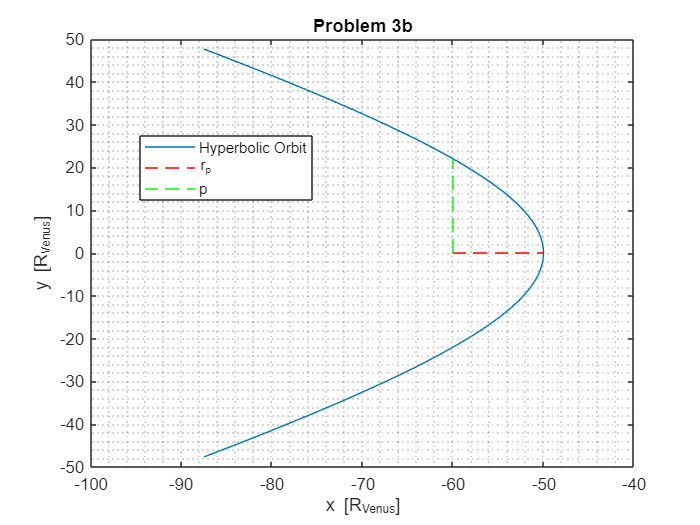

% Plot Orbit
ta_H_vec     = -120:.5:120;

% Initialize Perifocal position vector
r_P_H         = zeros(2,length(ta_H_vec)); 

for i = 1:length(ta_H_vec)
    
    % Calculate Hyperbolic anomaly
    H           = 2*atanh(tand(ta_H_vec(i)/2)/sqrt((1+e_H)/(e_H - 1)));

    % Position Vector in Perifocal Frame 
    r_P_H(:,i)  = [-a_abs_H*cosh(H);b*sinh(H)]; 

end

figure
plot(r_P_H(1,:),r_P_H(2,:))
title('Problem 3b')
grid minor
hold on
line([max(r_P_H(1,:))-rp_H max(r_P_H(1,:))],[0 0], 'Color','red','Linestyle','--')
line([max(r_P_H(1,:))-rp_H max(r_P_H(1,:))-rp_H],[0 p_H], 'Color','green','Linestyle','--')
xlabel('x [R_{Venus}]')
ylabel('y [R_{Venus}]')
xlim([-100 -40])
legend('Hyperbolic Orbit','r_p','p','Location','best')
hold off

## Problem 3d)

% Calculate velocity at periapsis
v_rp     = sqrt(2*(energy_H + mu_venus/rp_H));
fprintf('The velocity at periapsis is %.2f [km/s] \n',v_rp*6051.9) 

The velocity at periapsis is 3.44 [km/s] 



$$\epsilon = \frac{v^2}{2} - \frac{\mu}{r_{p} \\v = \sqrt{2(\epsilon + \frac{\mu}{{r_p}})}  =3.44 \ [km/s]$$
 

% Calculate velocity needed for circular orbit at periapsis
vc       = sqrt(mu_venus/rp_H);
fprintf('The velocity need for circular orbit at periapsis is %.2f [km/s] \n',vc*6051.9) 

The velocity need for circular orbit at periapsis is 2.32 [km/s] 



$$v_c = \sqrt{\frac{\mu}{r}} = 2.32 \ [km/s]$$


The **delta-v needed to drop into a circular orbit at an alitude equal to the periapsis is 1.12 [km/s]**. I would consider the delta-v needed to be delivered by the spacecraft a large amount. It is reducing the velocity at periapsis by 33%, but ultitmately it may depend on the mass properties of the spacecraft and the time needed to perform the manuever. If the spacecraft has large mass, it will take a large amount of force to quickly decelerate the spacecraft so that it can drop into a ciruclar orbit.

## Functions

function E = CalcEccentricAnomaly(e, M)
    
    % Initial Guess for Eccentric Anonmaly
    E           = M; 

    % Change in E to Enter while loop
    deltaE      = 1; 

    % While loop exit condition
    count       = 1; 

    % Error tolerace
    etol        = 1E-8;

    % Calculate E
        while abs(deltaE)> etol
    
            % Keplers Equation set to 0
            f       = M - (E - e*sin(E));

            % Derivative of Keplers equation with respect to E
            df      = -(1-e*cos(E));

            % Newton Raphson Equation
            E_nr  = E - (f/df); 

            % Calculate Change in E
            deltaE = E - E_nr; 

            % Reassign value of E
            E = E_nr; 
            
            % Increase counter
            count = count + 1;
    
                if count > 10000 % Break condition
                    disp('Max iteration reached')
                    break
                end
        end
end
